controller = mamfis(   ... 
    'NumInputs', 1,    ...
    'NumInputMFs', 2,  ...
    'NumOutputs', 1,   ...
    'NumOutputMFs', 2, ... 
    'AddRule', 'none'  ...
);


max_angle = pi/2; % In Rad

controller.Inputs(1).Name = 'CART_ANGLE'; 
controller.Inputs(1).Range = [-max_angle max_angle];
controller.Inputs(1).MembershipFunctions(1).Name = 'NEGATIVE'; 
controller.Inputs(1).MembershipFunctions(1).Type = 'zmf'; 
controller.Inputs(1).MembershipFunctions(1).Parameters = [-max_angle/2 max_angle/2]; 
controller.Inputs(1).MembershipFunctions(2).Name = 'POSITIVE'; 
controller.Inputs(1).MembershipFunctions(2).Type = 'smf'; 
controller.Inputs(1).MembershipFunctions(2).Parameters = [-max_angle/2 max_angle/2]; 


max_angular_velocity = 10; % In Rad/s

controller.Inputs(2).Name = 'CART_ANGULAR_VELOCITY'; 
controller.Inputs(2).Range = [-max_angular_velocity max_angular_velocity];
controller.Inputs(2).MembershipFunctions(1).Name = 'NEGATIVE'; 
controller.Inputs(2).MembershipFunctions(1).Type = 'zmf'; 
controller.Inputs(2).MembershipFunctions(1).Parameters = [-max_angular_velocity/2 max_angular_velocity/2]; 
controller.Inputs(2).MembershipFunctions(2).Name = 'POSITIVE'; 
controller.Inputs(2).MembershipFunctions(2).Type = 'smf'; 
controller.Inputs(2).MembershipFunctions(2).Parameters = [-max_angular_velocity/2 max_angular_velocity/2]; 

 
max_position = 1; % In m

controller.Inputs(3).Name = 'CART_POSITION'; 
controller.Inputs(3).Range = [-max_position max_position]; 
controller.Inputs(3).MembershipFunctions(1).Name = 'NEGATIVE'; 
controller.Inputs(3).MembershipFunctions(1).Type = 'zmf'; 
controller.Inputs(3).MembershipFunctions(1).Parameters = [-max_position/2 max_position/2]; 
controller.Inputs(3).MembershipFunctions(2).Name = 'POSITIVE'; 
controller.Inputs(3).MembershipFunctions(2).Type = 'smf'; 
controller.Inputs(3).MembershipFunctions(2).Parameters = [-max_position/2 max_position/2]; 


max_velocity = 10; % In m/s

controller.Inputs(4).Name = 'CART_VELOCITY'; 
controller.Inputs(4).Range = [-max_velocity max_velocity]; 
controller.Inputs(4).MembershipFunctions(1).Name = 'NEGATIVE'; 
controller.Inputs(4).MembershipFunctions(1).Type = 'zmf'; 
controller.Inputs(4).MembershipFunctions(1).Parameters = [-max_velocity/2 max_velocity/2]; 
controller.Inputs(4).MembershipFunctions(2).Name = 'POSITIVE'; 
controller.Inputs(4).MembershipFunctions(2).Type = 'smf'; 
controller.Inputs(4).MembershipFunctions(2).Parameters = [-max_velocity/2 max_velocity/2];

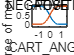

plotmf(controller, 'input', 1, 1000);

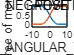

plotmf(controller, 'input', 2, 1000);

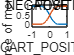

plotmf(controller, 'input', 3, 1000);

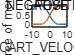

plotmf(controller, 'input', 4, 1000);

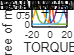


max_torque = 20; % In Nm

controller.Outputs(1).Name = 'TORQUE';
controller.Outputs(1).Range = [-max_torque, max_torque];

controller.Outputs(1).MembershipFunctions(1).Name = 'NEGATIVE_SMALL';
controller.Outputs(1).MembershipFunctions(1).Type = 'gbellmf'; 
controller.Outputs(1).MembershipFunctions(1).Parameters = [0.1*max_torque, 2, -0.1*max_torque]; 
controller.Outputs(1).MembershipFunctions(2).Name = 'POSITIVE_SMALL';
controller.Outputs(1).MembershipFunctions(2).Type = 'gbellmf'; 
controller.Outputs(1).membershipFunctions(2).Parameters = [0.1*max_torque, 2, 0.1*max_torque];

controller.Outputs(1).MembershipFunctions(3).Name = 'NEGATIVE_MEDIUM';
controller.Outputs(1).MembershipFunctions(3).Type = 'gbellmf'; 
controller.Outputs(1).MembershipFunctions(3).Parameters = [0.3*max_torque, 2, -0.6*max_torque]; 
controller.Outputs(1).MembershipFunctions(4).Name = 'POSITIVE_MEDIUM';
controller.Outputs(1).MembershipFunctions(4).Type = 'gbellmf'; 
controller.Outputs(1).membershipFunctions(4).Parameters = [0.3*max_torque, 2, 0.6*max_torque]; 

controller.Outputs(1).MembershipFunctions(5).Name = 'NEGATIVE_LARGE';
controller.Outputs(1).MembershipFunctions(5).Type = 'gbellmf'; 
controller.Outputs(1).MembershipFunctions(5).Parameters = [0.3*max_torque, 2, -max_torque]; 
controller.Outputs(1).MembershipFunctions(6).Name = 'POSITIVE_LARGE';
controller.Outputs(1).MembershipFunctions(6).Type = 'gbellmf'; 
controller.Outputs(1).membershipFunctions(6).Parameters = [0.3*max_torque, 2, max_torque]; 

plotmf(controller, 'output', 1, 1000);

rules = [ ...
    "If CART_ANGLE is NEGATIVE then TORQUE is NEGATIVE_MEDIUM";           ...
    "If CART_ANGLE is POSITIVE then TORQUE is POSITIVE_MEDIUM";           ...
    "If CART_ANGULAR_VELOCITY is NEGATIVE then TORQUE is NEGATIVE_LARGE"; ...
    "If CART_ANGULAR_VELOCITY is POSITIVE then TORQUE is POSITIVE_LARGE"; ...
    "If CART_POSITION is NEGATIVE then TORQUE is POSITIVE_SMALL";         ...
    "If CART_POSITION is POSITIVE then TORQUE is NEGATIVE_SMALL";         ...
    "If CART_VELOCITY is NEGATIVE then TORQUE is NEGATIVE_MEDIUM";        ...
    "If CART_VELOCITY is POSITIVE then TORQUE is POSITIVE_MEDIUM";        ...
];
controller = addRule(controller, rules);